addpath('~/uni/utils')

% Question 1
r1 = 3e3

r1 = 3000

r2 = 1e3

r2 = 1000

v_dd = 0.7

v_dd = 0.7000

r_d = 30

r_d = 30

v_th = vdiv(9, r1, r2)

v_th = 2.2500

r_th = zpar([r1 r2])

r_th = 750

i_d = (v_th - v_dd) / zser([r_th r_d])

i_d = 0.0020

v_d = v_dd + i_d * r_d

v_d = 0.7596

% Question 2 a
v_t = 25e-3

v_t = 0.0250

n = 1.5

n = 1.5000

i_d = 10e-3

i_d = 0.0100

v_d = 0.65

v_d = 0.6500

syms i_s
i_s = double(solve_for( ...
    i_s, ...
    diode_characteristic(n, v_t, v_d, i_d, i_s)))

i_s = 2.9664e-10


% saturation current is now known
syms v_d i_d
i_d2v_d = solve2fn(v_d, ...
    diode_characteristic(n, v_t, v_d, i_d, i_s), ...
    i_d)

i_d2v_d = function_handle with value:
    @(i_d)log(i_d.*3.371095119025709e+9+1.0).*(3.0./8.0e+1)


i_d2v_d(1e-3)

ans = 0.5637

i_d2v_d(5e-3)

ans = 0.6240

i_d2v_d(10e-3)

ans = 0.6500

i_d2v_d(20e-3)

ans = 0.6760


% Question 2 b
v_in = 6

v_in = 6

r = 470

r = 470

r_d = 30

r_d = 30

v_th = vdiv(v_in, r, r)

v_th = 3

r_th = zpar([r r])

r_th = 235


i_d_vd0 = v_th / r_th

i_d_vd0 = 0.0128

i_dq = 9.6e-3

i_dq = 0.0096


figure; hold on
plot([0 3], [i_d_vd0 0])
v_d_sweep = 0:0.01:1

v_d_sweep =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


v_d2i_d = solve2fn(i_d, ...
    diode_characteristic(n, v_t, v_d, i_d, i_s), ...
    v_d)

v_d2i_d = function_handle with value:
    @(v_d)exp(v_d.*(8.0e+1./3.0)).*2.966395087329998e-10-2.966395087329998e-10


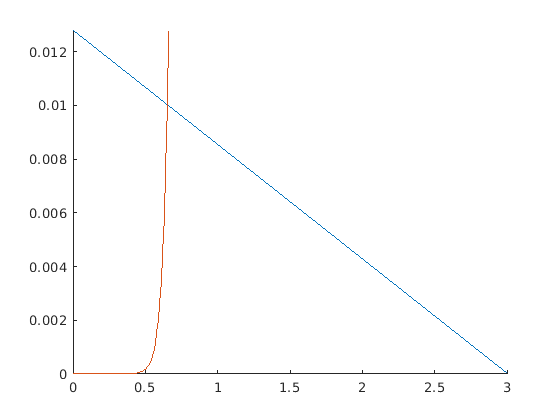

plot(v_d_sweep, v_d2i_d(v_d_sweep))
ylim([0 i_d_vd0])


% Quesiton 2 c
r_dq = n * v_t / i_dq

r_dq = 3.9063

syms Vin
r1 = 2e3

r1 = 2000

r2 = 1e3

r2 = 1000

r3 = 1e3

r3 = 1000

Vd = 0.7

Vd = 0.7000

Vt = vdiv(Vin, r1, r2)

$$Vt = \frac{\mathrm{Vin}}{3}$$

rt = zpar([r1 r2])

rt = 666.6667

Id = vpa((Vt - 0.7) / zser([rt r3]), 3)

$$Id = 2.0e-4\,\mathrm{Vin}-4.2e-4$$

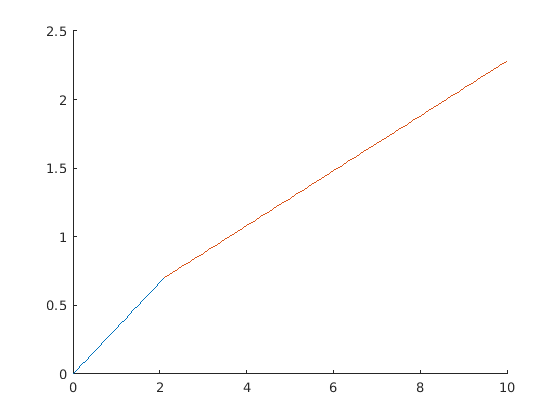


Vin1 = 0:0.1:2.1;
Vo1 = Vin1 / 3;

Vin2 = 2.1:0.1:10;
Vo2 = 0.7 + 3 / 5 * (Vin2 / 3 - 0.7);

figure; hold on
plot(Vin1, Vo1)
plot(Vin2, Vo2)